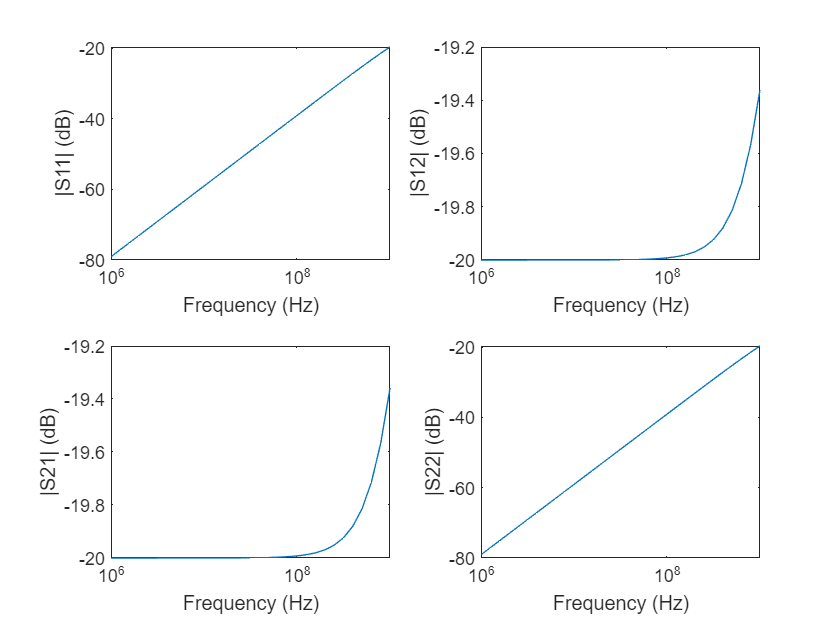

% 20 dB T attenuator with resistors having parallel capacitance
import MCIR.*
cir = Circuit('S-Parameter analysis');
cir <= 'PORT1 1 0 50'
cir <= 'R1a 1 x 40.9091'
cir <= 'R1b x 2 40.9091'
cir <= 'R2 x 0 10.1010'
cir <= 'C2 x 0 1.0p Rser=10'
cir <= 'C1a 1 x 1.0p Rser=40'
cir <= 'C1b x 2 1.0p Rser=40'
cir <= 'PORT2 2 0 50'

cir.net('S', 'dec',1e6,1000e6,10);